# introdução ao matLab

clear all;      % limpa variaveis
close all;      % limpa os graficos / figuras
clc;            % limpa a tela
% ; -> esconde do console

## Definindo variaveis

A = 1           % variavel real

A = 1

B = 1 + j       % variavel complexa

B = 1.0000 + 1.0000i

C = magic(3)    % matriz

C =      8     1     6
     3     5     7
     4     9     2


D = rand(7)     % aleatoria

D =     0.7519    0.4190    0.5056    0.3551    0.0251    0.5710    0.0875
    0.2287    0.3908    0.6357    0.9970    0.4211    0.1769    0.6401
    0.0642    0.8161    0.9509    0.2242    0.1841    0.9574    0.1806
    0.7673    0.3174    0.4440    0.6525    0.7258    0.2653    0.0451
    0.6712    0.8145    0.0600    0.6050    0.3704    0.9246    0.7232
    0.7152    0.7891    0.8667    0.3872    0.8416    0.2238    0.3474
    0.6421    0.8523    0.6312    0.1422    0.7342    0.3736    0.6606


## Operações logicas

E = find(C == 5)

E = 5

[i,j,v] = find(C == 9)

i = 3

j = 2

v = logical
   1


F = [1,2,3,4,5,6,7,8,9]

F =      1     2     3     4     5     6     7     8     9


F>5

ans = 1×9 logical array
   0   0   0   0   0   1   1   1   1


## Operações simbolicas

syms t a                     % variaveis simbolicas
I = int(exp(-a*t),t,0,1)     % integral   

$$I = -\frac{{\mathrm{e}}^{-a}-1}{a}$$

a = 1;
eval(I)                      % calcula numericamente

ans = 0.6321

## Funções handle

g = @(a,t) exp(-a*t)        % definindo uma função

g = function_handle with value:
    @(a,t)exp(-a*t)


g(1,1)                      % usando a função

ans = 0.3679

## Documentação e visualização

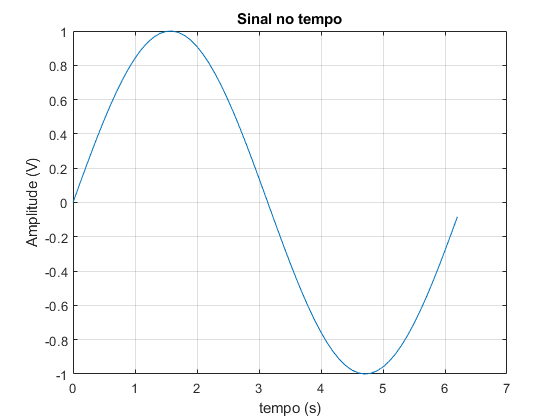

tempo = [0:0.1:2*pi];
y = sin(tempo);

figure(1)

plot(tempo,y);
title('Sinal no tempo');
xlabel('tempo (s)');
ylabel('Amplitude (V)');
grid;


y1 = sin(2*tempo);

figure(2)
plot(tempo,y);hold;plot(tempo,y1);

Current plot held


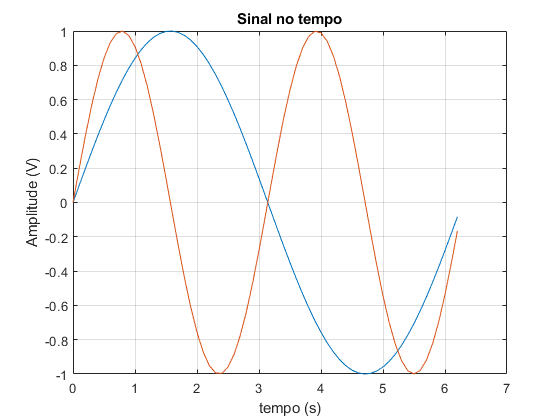

title('Sinal no tempo');
xlabel('tempo (s)');
ylabel('Amplitude (V)');
grid;


$$g = \int_0^2 x^2 dx$$


## Arquivos externos

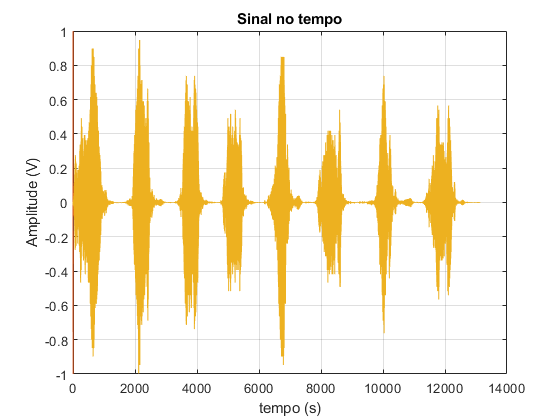

load chirp

plot(y)

sound(y)

Xp = mean(y) % media

Xp = 2.3052e-04

Vp = var(y) % variancia

Vp = 0.0373

Yc = [y:y] % concatena

Yc = -0.0015

Y1 = [y' y'] % concatena

Y1 =    -0.0015         0   -0.0008   -0.0127    0.0038   -0.0077   -0.0115    0.0046   -0.0173    0.0046   -0.0008   -0.0092    0.0115   -0.0092    0.0008    0.0085   -0.0046    0.0038    0.0188   -0.0100    0.0235    0.0015   -0.0038    0.0342   -0.0250    0.0250   -0.0085   -0.0108    0.0381   -0.0265    0.0235    0.0062   -0.0381    0.0565   -0.0381    0.0127    0.0281   -0.0688    0.0950   -0.0781    0.0358    0.0265   -0.0888    0.1135   -0.0842    0.0235    0.0381   -0.1012    0.1196   -0.0812


Ep = y.^2  % determina array

Ep =     0.0024
         0
    0.0006
    0.1611
    0.0148
    0.0592
    0.1331
    0.0213
    0.2996
    0.0213


## Estrutura de dados

D = {}


D =

  0×0 empty cell array



D.data = Yc

D = struct with fields:
    data: -0.0015


D.tempo = tempo

D = struct with fields:
     data: -0.0015
    tempo: [1×63 double]
